Vishnu Radhakrihsnan

CB.EN.U4AIE20074

IN class Wavelet reconstruction

clc
clear all
close all
n=1024;
x=MakeSignal('Piece-Regular',n);
x=rescale(x,0.05,0.95);
sigma=0.2;
x0=x+rand(size(x)).*sigma;
subplot(4,1,1);plot(x);title('Signal')
subplot(4,1,2);plot(x0);title('Signal with noise')
f=fft(x);
f(50:1024)=0;
x2=ifft(f);
subplot(4,1,3);plot(real(x2));title('Reconstructed using Fourier')
[c s]=wavedec(x0,4,'haar')

c =    0.723985276787290   0.697878264914245   0.749927102325008   0.966847351111722   1.245378596128656   1.756424876275325   2.288679744469562   3.084539444931563   3.810046532815540   2.828983360630538   2.557676887058875   2.584581449846597   2.635914818346869   3.291573808558212   2.521355142539181   1.883088187653621   1.464060816969466   0.904196221470424   0.733224191729532   0.591900668076987   0.660854052755177   0.668685511444377   0.667483723270278   0.846548674893601   1.339669947834195   3.004568142955418   1.369818993548677   1.076349915102063   1.171324261947717   0.648708676501523   0.657311510541249   0.617876203884794   0.593598561206256   0.840959802697683   0.944137280758066   1.369140725615645   2.445785876882622   3.310305505608831   1.965604386974857   1.242912798550122   0.952691453936608   0.785448042263432   0.658201869411133   0.629706363127553   0.626735561913117   0.846341244592821   1.993432130509090   2.018945591661574   2.038781821876956   2.03825038111

s =           64          64         128         256         512        1024


c1=c.*(abs(c)>2*sigma)

c1 =    0.723985276787290   0.697878264914245   0.749927102325008   0.966847351111722   1.245378596128656   1.756424876275325   2.288679744469562   3.084539444931563   3.810046532815540   2.828983360630538   2.557676887058875   2.584581449846597   2.635914818346869   3.291573808558212   2.521355142539181   1.883088187653621   1.464060816969466   0.904196221470424   0.733224191729532   0.591900668076987   0.660854052755177   0.668685511444377   0.667483723270278   0.846548674893601   1.339669947834195   3.004568142955418   1.369818993548677   1.076349915102063   1.171324261947717   0.648708676501523   0.657311510541249   0.617876203884794   0.593598561206256   0.840959802697683   0.944137280758066   1.369140725615645   2.445785876882622   3.310305505608831   1.965604386974857   1.242912798550122   0.952691453936608   0.785448042263432   0.658201869411133   0.629706363127553   0.626735561913117   0.846341244592821   1.993432130509090   2.018945591661574   2.038781821876956   2.0382503811

x3=waverec(c1,s,'haar')

x3 =    0.180996319196823   0.180996319196823   0.180996319196823   0.180996319196823   0.180996319196823   0.180996319196823   0.180996319196823   0.180996319196823   0.180996319196823   0.180996319196823   0.180996319196823   0.180996319196823   0.180996319196823   0.180996319196823   0.180996319196823   0.180996319196823   0.174469566228561   0.174469566228561   0.174469566228561   0.174469566228561   0.174469566228561   0.174469566228561   0.174469566228561   0.174469566228561   0.174469566228561   0.174469566228561   0.174469566228561   0.174469566228561   0.174469566228561   0.174469566228561   0.174469566228561   0.174469566228561   0.187481775581252   0.187481775581252   0.187481775581252   0.187481775581252   0.187481775581252   0.187481775581252   0.187481775581252   0.187481775581252   0.187481775581252   0.187481775581252   0.187481775581252   0.187481775581252   0.187481775581252   0.187481775581252   0.187481775581252   0.187481775581252   0.241711837777930   0.2417118377

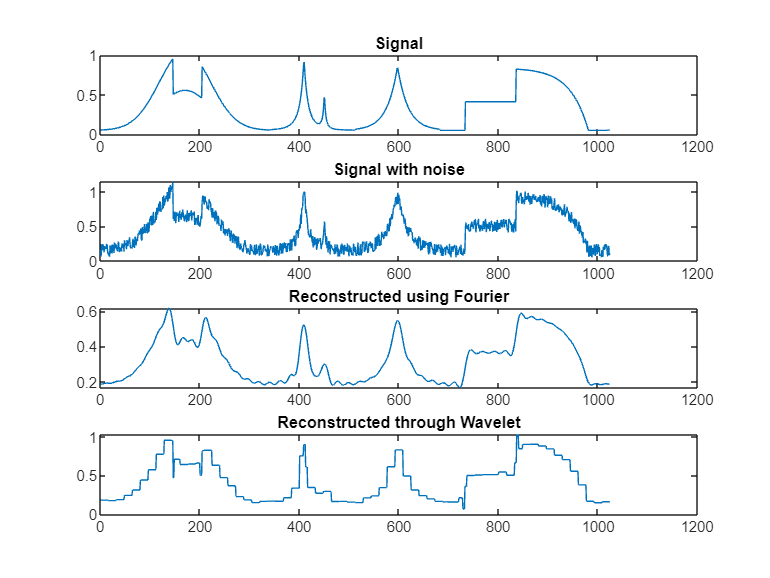

subplot(4,1,4);plot(x3);title('Reconstructed through Wavelet')

FD_psnr=psnr(x0,real(x2))

FD_psnr =   15.109246602587614


WD_psnr=psnr(x0,real(x3))

WD_psnr =   22.693758678050735


function sig = MakeSignal(Name,n)
% MakeSignal -- Make artificial signal
%  Usage
%    sig = MakeSignal(Name,n)
%  Inputs
%    Name   string: 'HeaviSine', 'Bumps', 'Blocks',
%            'Doppler', 'Ramp', 'Cusp', 'Sing', 'HiSine',
%            'LoSine', 'LinChirp', 'TwoChirp', 'QuadChirp',
%            'MishMash', 'WernerSorrows' (Heisenberg),
%            'Leopold' (Kronecker), 'Piece-Regular' (Piece-Wise Smooth),
%	     'Riemann','HypChirps','LinChirps', 'Chirps', 'Gabor'
%	     'sineoneoverx','Cusp2','SmoothCusp','Gaussian'
%	     'Piece-Polynomial' (Piece-Wise 3rd degree polynomial)
%    n      desired signal length
%  Outputs
%    sig    1-d signal
%
%  References
%    Various articles of D.L. Donoho and I.M. Johnstone
%
   if nargin > 1,
	t = (1:n) ./n;
   end
	if strcmp(Name,'HeaviSine'),
	    sig = 4.*sin(4*pi.*t);
	    sig = sig - sign(t - .3) - sign(.72 - t);
	elseif strcmp(Name,'Bumps'),
	    pos = [ .1 .13 .15 .23 .25 .40 .44 .65  .76 .78 .81];
	    hgt = [ 4  5   3   4  5  4.2 2.1 4.3  3.1 5.1 4.2];
	    wth = [.005 .005 .006 .01 .01 .03 .01 .01  .005 .008 .005];
	    sig = zeros(size(t));
	    for j =1:length(pos)
	       sig = sig + hgt(j)./( 1 + abs((t - pos(j))./wth(j))).^4;
	    end 
	elseif strcmp(Name,'Blocks'),
	    pos = [ .1 .13 .15 .23 .25 .40 .44 .65  .76 .78 .81];
	    hgt = [4 (-5) 3 (-4) 5 (-4.2) 2.1 4.3  (-3.1) 2.1 (-4.2)];
	    sig = zeros(size(t));
	    for j=1:length(pos)
	        sig = sig + (1 + sign(t-pos(j))).*(hgt(j)/2) ;
	    end
	elseif strcmp(Name,'Doppler'),
	    sig = sqrt(t.*(1-t)).*sin((2*pi*1.05) ./(t+.05));
	elseif strcmp(Name,'Ramp'),
	    sig = t - (t >= .37);
	elseif strcmp(Name,'Cusp'),
	    sig = sqrt(abs(t - .37));
	elseif strcmp(Name,'Sing'),
	    k = floor(n * .37);
	    sig = 1 ./abs(t - (k+.5)/n);
	elseif strcmp(Name,'HiSine'),
	    sig = sin( pi * (n * .6902) .* t);
	elseif strcmp(Name,'LoSine'),
	    sig = sin( pi * (n * .3333) .* t);
	elseif strcmp(Name,'LinChirp'),
	    sig = sin(pi .* t .* ((n .* .500) .* t));
	elseif strcmp(Name,'TwoChirp'),
	    sig = sin(pi .* t .* (n .* t)) + sin((pi/3) .* t .* (n .* t));
	elseif strcmp(Name,'QuadChirp'),
	    sig = sin( (pi/3) .* t .* (n .* t.^2));
	elseif strcmp(Name,'MishMash'),  % QuadChirp + LinChirp + HiSine
	    sig = sin( (pi/3) .* t .* (n .* t.^2)) ;
	    sig = sig +  sin( pi * (n * .6902) .* t);
	    sig = sig +  sin(pi .* t .* (n .* .125 .* t));
	elseif strcmp(Name,'WernerSorrows'),
	    sig = sin( pi .* t .* (n/2 .* t.^2)) ;
	    sig = sig +  sin( pi * (n * .6902) .* t);
	    sig = sig +  sin(pi .* t .* (n .* t));
	    pos = [ .1 .13 .15 .23 .25 .40 .44 .65  .76 .78 .81];
	    hgt = [ 4  5   3   4  5  4.2 2.1 4.3  3.1 5.1 4.2];
	    wth = [.005 .005 .006 .01 .01 .03 .01 .01  .005 .008 .005];
	    for j =1:length(pos)
	       sig = sig + hgt(j)./( 1 + abs((t - pos(j))./wth(j))).^4;
	    end 
	elseif strcmp(Name,'Leopold'),
	    sig = (t == floor(.37 * n)/n);  % Kronecker
	elseif strcmp(Name,'Riemann'),
		sqn = round(sqrt(n));
	    sig = t .* 0;  % Riemann's Non-differentiable Function
		sig((1:sqn).^2) = 1. ./ (1:sqn);
		sig = real(ifft(sig));
	elseif strcmp(Name,'HypChirps'), % Hyperbolic Chirps of Mallat's book
		alpha	= 15*n*pi/1024;
		beta    = 5*n*pi/1024;
		t  	= (1.001:1:n+.001)./n; 
		f1      = zeros(1,n);
		f2      = zeros(1,n);	
		f1  	= sin(alpha./(.8-t)).*(0.1<t).*(t<0.68);
		f2  	= sin(beta./(.8-t)).*(0.1<t).*(t<0.75);
		M  	= round(0.65*n);
		P 	= floor(M/4);
		enveloppe = ones(1,M); % the rising cutoff function 
            enveloppe(1:P) = (1+sin(-pi/2+((1:P)-ones(1,P))./(P-1)*pi))/2;
            enveloppe(M-P+1:M) = reverse(enveloppe(1:P));
  		env 	= zeros(1,n);
  		env(ceil(n/10):M+ceil(n/10)-1) = enveloppe(1:M);
		sig     = (f1+f2).*env;
	elseif strcmp(Name,'LinChirps'), % Linear Chirps of Mallat's book
		b 	= 100*n*pi/1024;
		a 	= 250*n*pi/1024;
		t 	= (1:n)./n; 
		A1 	= sqrt((t-1/n).*(1-t));
		sig	= A1.*(cos((a*(t).^2)) + cos((b*t+a*(t).^2)));
	elseif strcmp(Name,'Chirps'), % Mixture of Chirps of Mallat's book
		t 	= (1:n)./n.*10.*pi;  
  		f1 	= cos(t.^2*n/1024);
		a 	= 30*n/1024;
  		t 	= (1:n)./n.*pi;  
  		f2 	= cos(a.*(t.^3));
  		f2 	= reverse(f2);
		ix 	= (-n:n)./n.*20;
 		g 	= exp(-ix.^2*4*n/1024);
		i1 	= (n/2+1:n/2+n);
		i2 	= (n/8+1:n/8+n);
		j  	= (1:n)/n;
    		f3 	= g(i1).*cos(50.*pi.*j*n/1024);
		f4 	= g(i2).*cos(350.*pi.*j*n/1024);
		sig 	= f1+f2+f3+f4;
   	 enveloppe = ones(1,n); % the rising cutoff function 
  	 enveloppe(1:n/8) = (1+sin(-pi/2+((1:n/8)-ones(1,n/8))./(n/8-1)*pi))/2;
  	 enveloppe(7*n/8+1:n) = reverse(enveloppe(1:n/8));
 		sig 	= sig.*enveloppe;
        elseif strcmp(Name,'Gabor'), % two modulated Gabor functions in 
				     % Mallat's book
		N = 512;	
   		t = (-N:N)*5/N;
        	j = (1:N)./N;
		g = exp(-t.^2*20);
		i1 = (2*N/4+1:2*N/4+N);
		i2 = (N/4+1:N/4+N);
		sig1 = 3*g(i1).*exp(i*N/16.*pi.*j);
		sig2 = 3*g(i2).*exp(i*N/4.*pi.*j);
   		sig = sig1+sig2;
	elseif strcmp(Name,'sineoneoverx'), % sin(1/x) in Mallat's book
		N = 1024;
		a = (-N+1:N);
		a(N) = 1/100;
		a = a./(N-1);
		sig = sin(1.5./(i));
		sig = sig(513:1536);
	elseif strcmp(Name,'Cusp2'),
		N = 64;
		a = (1:N)./N;
		x = (1-sqrt(a)) + a/2 -.5;
		M = 8*N;
		sig = zeros(1,M);
		sig(M-1.5.*N+1:M-.5*N) = x;
		sig(M-2.5*N+2:M-1.5.*N+1) = reverse(x);
		sig(3*N+1:3*N + N) = .5*ones(1,N);
	elseif strcmp(Name,'SmoothCusp'),
		sig = MakeSignal('Cusp2');
		N = 64;
		M = 8*N;
		t = (1:M)/M;
		sigma = 0.01;
		g = exp(-.5.*(abs(t-.5)./sigma).^2)./sigma./sqrt(2*pi);
		g = fftshift(g);
		sig2 = iconv(g',sig)'/M; 
   	elseif strcmp(Name,'Piece-Regular'),
		sig1=-15*MakeSignal('Bumps',n);
		t = (1:fix(n/12)) ./fix(n/12);
		sig2=-exp(4*t);
		t = (1:fix(n/7)) ./fix(n/7);
		sig5=exp(4*t)-exp(4);
		t = (1:fix(n/3)) ./fix(n/3);
		sigma=6/40;
		sig6=-70*exp(-((t-1/2).*(t-1/2))/(2*sigma^2));
		sig(1:fix(n/7))= sig6(1:fix(n/7));
		sig((fix(n/7)+1):fix(n/5))=0.5*sig6((fix(n/7)+1):fix(n/5));
		sig((fix(n/5)+1):fix(n/3))=sig6((fix(n/5)+1):fix(n/3));
		sig((fix(n/3)+1):fix(n/2))=sig1((fix(n/3)+1):fix(n/2));
		sig((fix(n/2)+1):(fix(n/2)+fix(n/12)))=sig2;
		sig((fix(n/2)+2*fix(n/12)):-1:(fix(n/2)+fix(n/12)+1))=sig2;
sig(fix(n/2)+2*fix(n/12)+fix(n/20)+1:(fix(n/2)+2*fix(n/12)+3*fix(n/20)))=...
-ones(1,fix(n/2)+2*fix(n/12)+3*fix(n/20)-fix(n/2)-2*fix(n/12)-fix(n/20))*25;
		k=fix(n/2)+2*fix(n/12)+3*fix(n/20);
		sig((k+1):(k+fix(n/7)))=sig5;
		diff=n-5*fix(n/5);
		sig(5*fix(n/5)+1:n)=sig(diff:-1:1);
		% zero-mean
		bias=sum(sig)/n;
		sig=bias-sig;
   	elseif strcmp(Name,'Piece-Polynomial'),
		t = (1:fix(n/5)) ./fix(n/5);
		sig1=20*(t.^3+t.^2+4);
		sig3=40*(2.*t.^3+t) + 100;
		sig2=10.*t.^3 + 45;
		sig4=16*t.^2+8.*t+16;
		sig5=20*(t+4);
		sig6(1:fix(n/10))=ones(1,fix(n/10));
		sig6=sig6*20;
		sig(1:fix(n/5))=sig1;
		sig(2*fix(n/5):-1:(fix(n/5)+1))=sig2;
		sig((2*fix(n/5)+1):3*fix(n/5))=sig3;
		sig((3*fix(n/5)+1):4*fix(n/5))=sig4;
		sig((4*fix(n/5)+1):5*fix(n/5))=sig5(fix(n/5):-1:1);
		diff=n-5*fix(n/5);
		sig(5*fix(n/5)+1:n)=sig(diff:-1:1);
		%sig((fix(n/20)+1):(fix(n/20)+fix(n/10)))=-ones(1,fix(n/10))*20;
		sig((fix(n/20)+1):(fix(n/20)+fix(n/10)))=ones(1,fix(n/10))*10;
		sig((n-fix(n/10)+1):(n+fix(n/20)-fix(n/10)))=ones(1,fix(n/20))*150;
		% zero-mean
		bias=sum(sig)/n;
		sig=sig-bias;
   	elseif strcmp(Name,'Gaussian'),
		sig=GWN(n,beta);
		g=zeros(1,n);
		lim=alpha*n;
		mult=pi/(2*alpha*n);
		g(1:lim)=(cos(mult*(1:lim))).^2;
		g((n/2+1):n)=g((n/2):-1:1);
		g = rnshift(g,n/2);
		g=g/norm(g);
		sig=iconv(g,sig);
       else
	    disp(sprintf('MakeSignal: I don*t recognize <<%s>>',Name))
	    disp('Allowable Names are:')
	       disp('HeaviSine'),
	       disp('Bumps'),
	       disp('Blocks'),
	       disp('Doppler'),
	       disp('Ramp'),
	       disp('Cusp'),
	       disp('Crease'),
	       disp('Sing'),
	       disp('HiSine'),
	       disp('LoSine'),
	       disp('LinChirp'),
	       disp('TwoChirp'),
	       disp('QuadChirp'),
	       disp('MishMash'),
	       disp('WernerSorrows'),
	       disp('Leopold'),
	       disp('Sing'),
	       disp('HiSine'),
	       disp('LoSine'),
	       disp('LinChirp'),
	       disp('TwoChirp'),
	       disp('QuadChirp'),
	       disp('MishMash'),
	       disp('WernerSorrows'),
	       disp('Leopold'),
	       disp('Riemann'),
	       disp('HypChirps'),
	       disp('LinChirps'),
	       disp('Chirps'),
	       disp('sineoneoverx'),
	       disp('Cusp2'),
	       disp('SmoothCusp'),
	       disp('Gabor'),
	       disp('Piece-Regular');
	       disp('Piece-Polynomial');
	       disp('Gaussian');
	end
	
%
% Originally made by David L. Donoho.
% Function has been enhanced.
    
    
%   
% Part of WaveLab Version 802
% Built Sunday, October 3, 1999 8:52:27 AM
% This is Copyrighted Material
% For Copying permissions see COPYING.m
% Comments? e-mail wavelab@stat.stanford.edu
%   
    
end